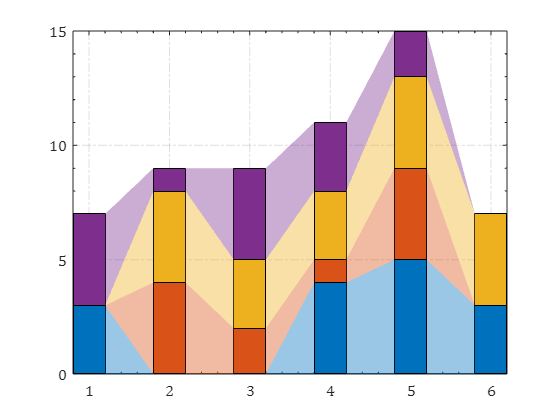

defualtAxes()
X=randi([0,5],[6,4]);
% X=randi([-2,5],[6,4]);
barHdl=bar(X,'stacked','BarWidth',.4);


% 以下是生成连接的部分
hold on;axis tight
yEndPoints=reshape([barHdl.YEndPoints]',length(barHdl(1).YData),[])';
zeros(1,length(barHdl(1).YData));
yEndPoints=[zeros(1,length(barHdl(1).YData));yEndPoints];
barWidth=barHdl(1).BarWidth;
for i=1:length(barHdl)
    for j=1:length(barHdl(1).YData)-1
        y1=min(yEndPoints(i,j),yEndPoints(i+1,j));
        y2=max(yEndPoints(i,j),yEndPoints(i+1,j));
        if y1*y2<0
            ty=yEndPoints(find(yEndPoints(i+1,j)*yEndPoints(1:i,j)>=0,1,'last'),j);
            y1=min(ty,yEndPoints(i+1,j));
            y2=max(ty,yEndPoints(i+1,j));
        end
        y3=min(yEndPoints(i,j+1),yEndPoints(i+1,j+1));
        y4=max(yEndPoints(i,j+1),yEndPoints(i+1,j+1));
        if y3*y4<0
            ty=yEndPoints(find(yEndPoints(i+1,j+1)*yEndPoints(1:i,j+1)>=0,1,'last'),j+1);
            y3=min(ty,yEndPoints(i+1,j+1));
            y4=max(ty,yEndPoints(i+1,j+1));
        end
        fill([j+.5.*barWidth,j+1-.5.*barWidth,j+1-.5.*barWidth,j+.5.*barWidth],...
            [y1,y3,y4,y2],barHdl(i).FaceColor,'FaceAlpha',.4,'EdgeColor','none');
    end
end